# load the data

## The order of the data is

exp1 = load_experiment_data('data_15870_0.csv',1);
exp2 = load_experiment_data('data_15870_2.csv',1);
exp3 = load_experiment_data('data_15870_3.csv',1);
exp4 = load_experiment_data('data_15870_5.csv',1);
exp5 = load_experiment_data('data_15870_6.csv',1);
exp6 = load_experiment_data('data_15870_8.csv',1);
exp7 = load_experiment_data('data_15870_9.csv',1);
exp8 = load_experiment_data('racecar_walker_cclockwise_1.5.csv',1);
exp9 = load_experiment_data('racecar_walker_clockwise_1.0.csv',1);
exp10 = load_experiment_data('racecar_walker_clockwise_1.5.csv',1);

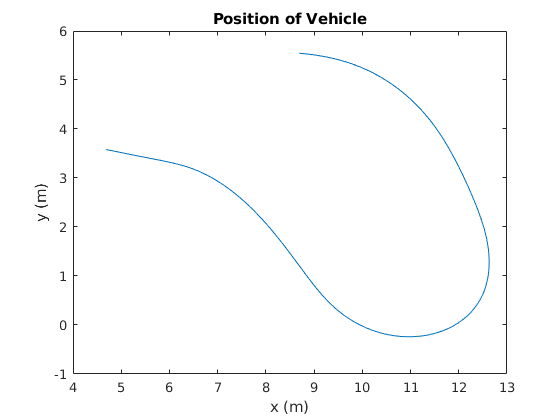

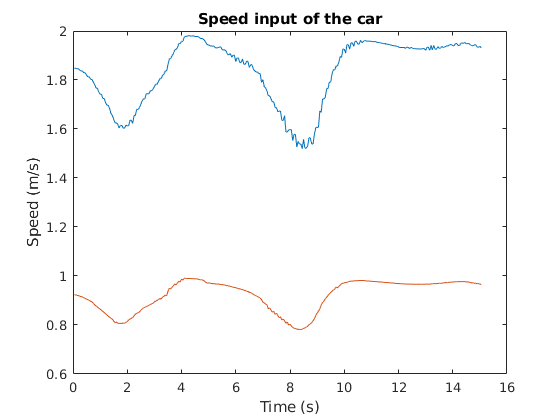

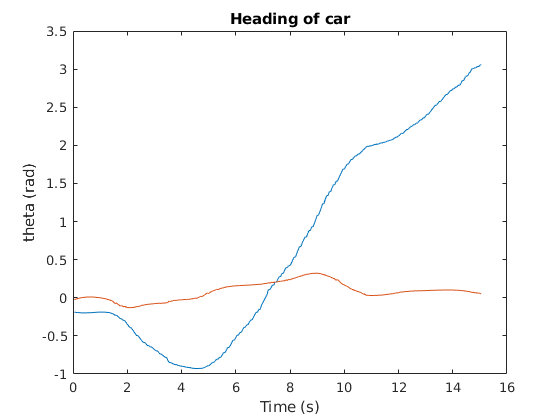

plot_race(exp1);

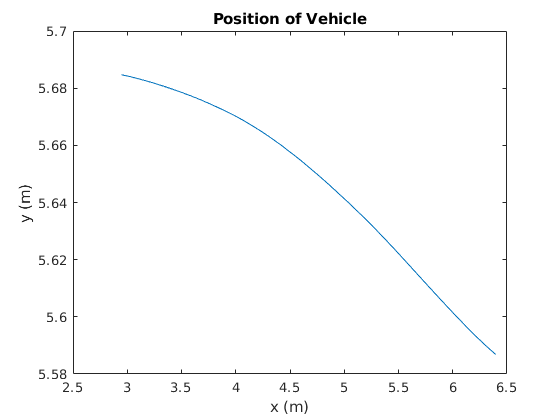

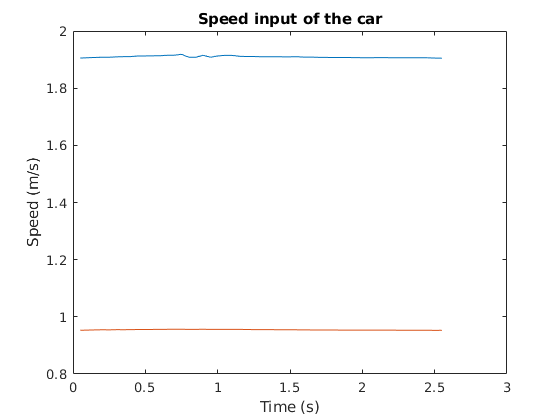

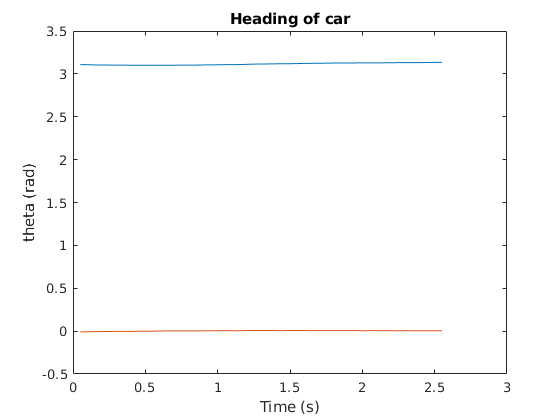

plot_race(exp2);

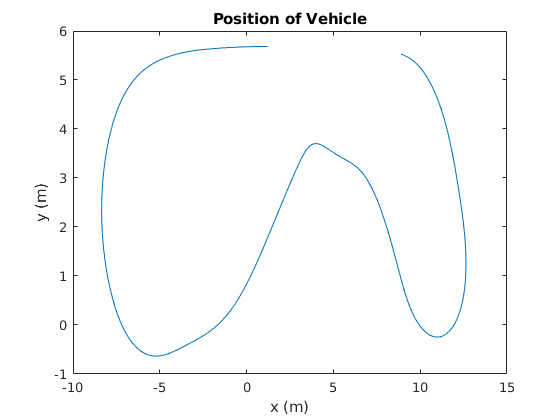

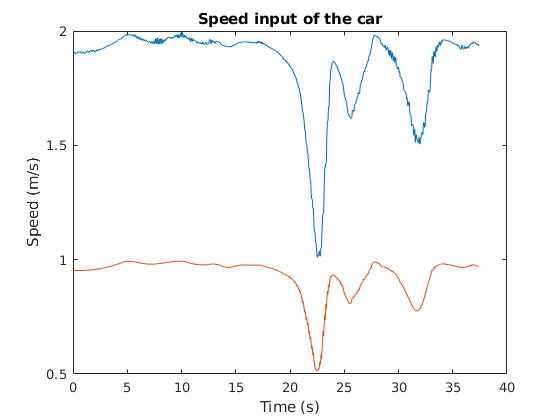

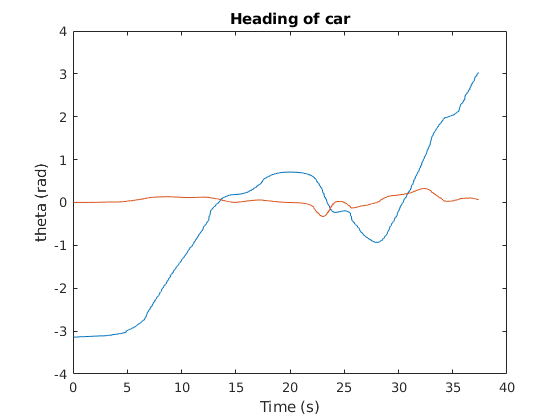

plot_race(exp3);

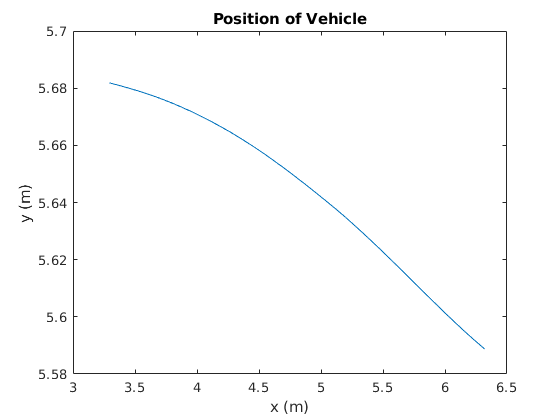

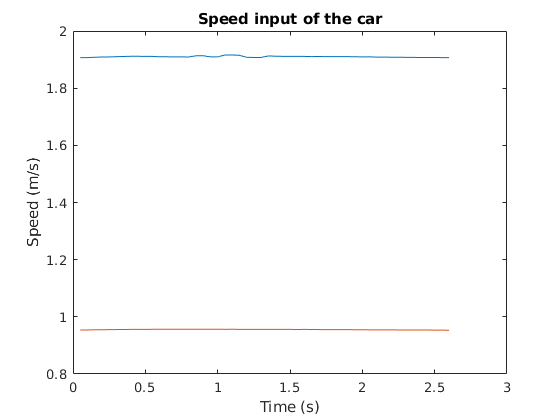

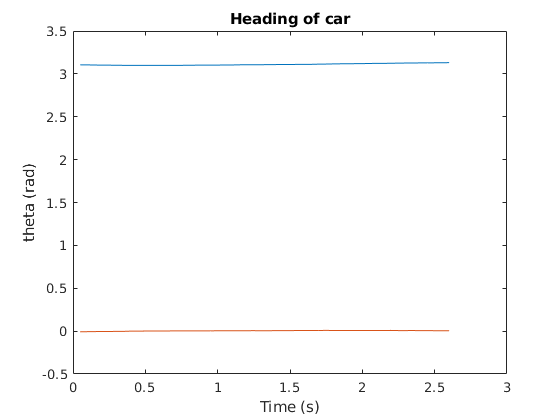

plot_race(exp4);

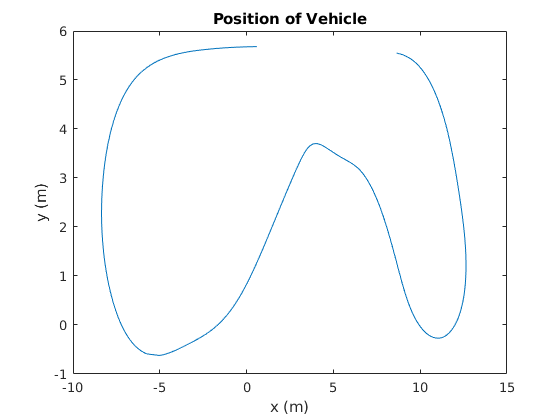

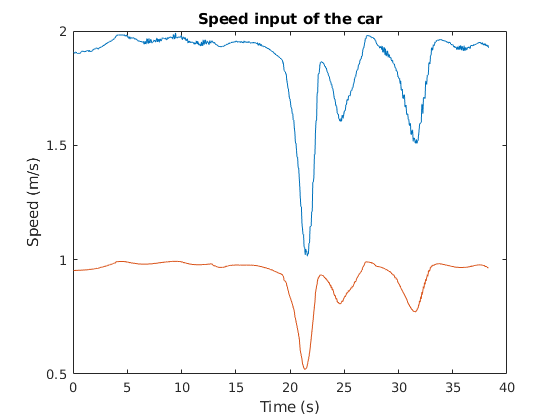

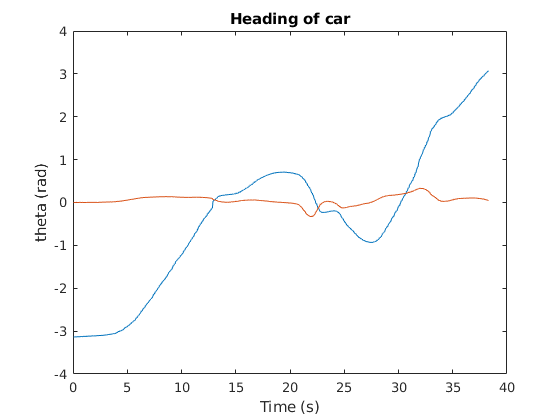

plot_race(exp5);

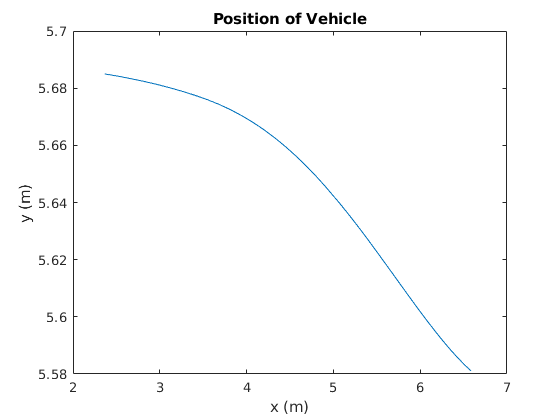

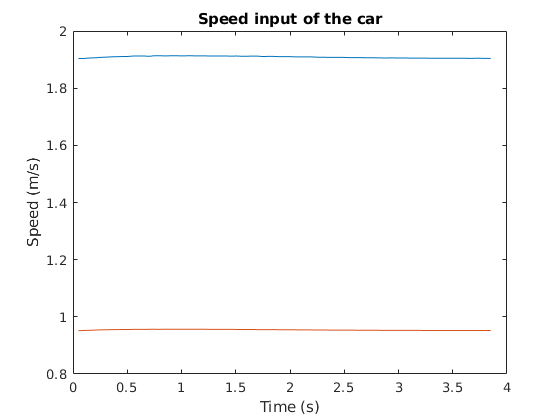

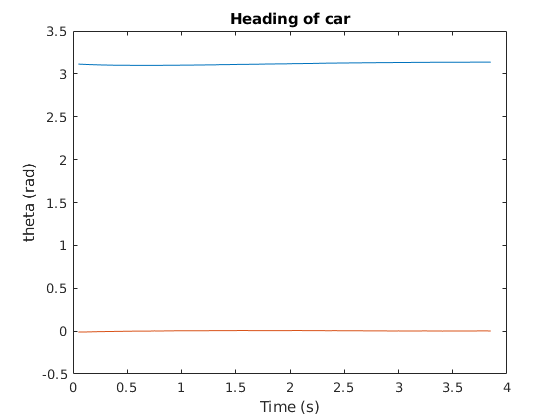

plot_race(exp6);

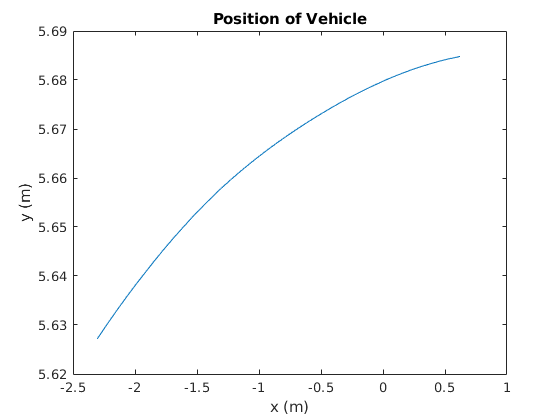

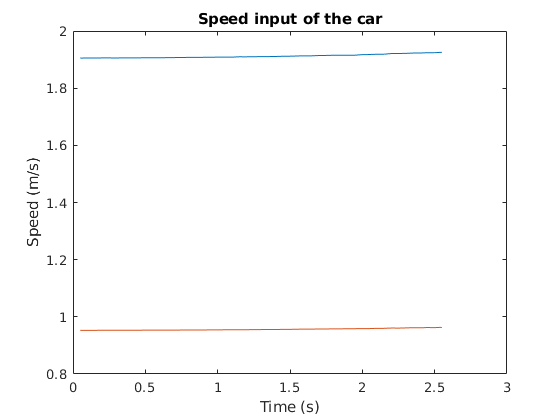

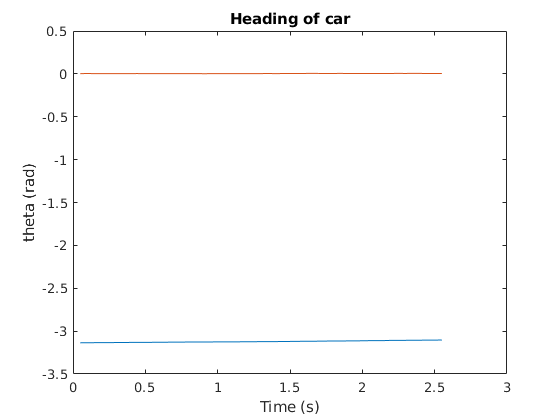

plot_race(exp7);

% Merge the data
data_est = merge(exp1,exp2,exp3,exp4,exp5,exp6,exp7);
data_est2 = merge(exp8,exp9,exp10);
data_est3 = merge(exp8);

% Let's try the system identification now

% specify the initial parameters
 ca = 1.1418;
 cm = 0.0092; 
 ch = -120.63;
 lf = 0.225;%0.255;
 lr = 0.225;%0.225;

% not sure why they call it order
% it species the number of model outputs
% the model inputs, and states
% so for us its 2 inputs, 4 outputs, 4 states

order         = [4 2 4];
parameters    = {ca,cm,ch,lf,lr};
initial_states = reshape(data_est.y(1,:),[],1);
Ts = 0;
nonlinear_model = idnlgrey('bicycle_model',order,parameters,initial_states,Ts);
nonlinear_model.algorithm.SimulationOptions.Solver = 'ode45';
nonlinear_model.algorithm.SimulationOptions.MaxStep = 1e-1;
nonlinear_model.algorithm.SimulationOptions.InitialStep = 1e-4;
nonlinear_model.SimulationOptions.AbsTol = 1e-6;
nonlinear_model.SimulationOptions.RelTol = 1e-5;
setpar(nonlinear_model,'Fixed',{false, false,false,true,true});

% Do the estimation 
opt = nlgreyestOptions;
opt.Display = 'Full';
opt.SearchOptions.FunctionTolerance = 1e-7;
opt.SearchOptions.MaxIterations = 100;
nonlinear_model = nlgreyest(data_est3,nonlinear_model,opt);

% get the parameters
b_est = nonlinear_model.Parameters

b_est = 5×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


% compare the learned model to the data 
figure();

res= compare(data_est,nonlinear_model)

res = 1×8 cell array
    {301×4×0 iddata}    {51×4×0 iddata}    {748×4×0 iddata}    {52×4×0 iddata}    {766×4×0 iddata}    {77×4×0 iddata}    {51×4×0 iddata}    {660×4×0 iddata}


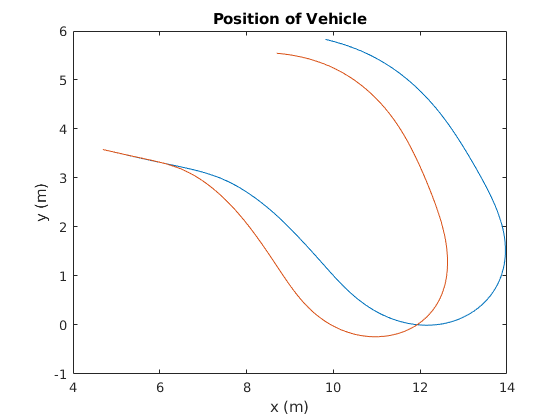

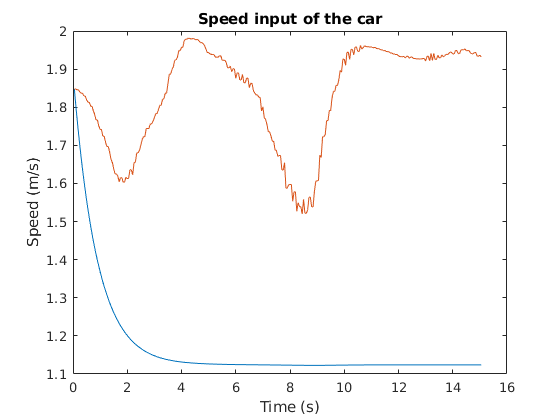

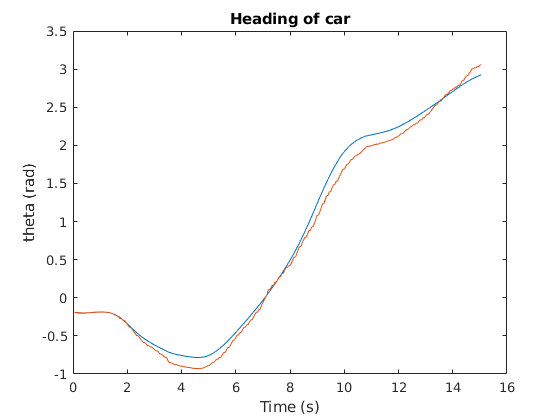

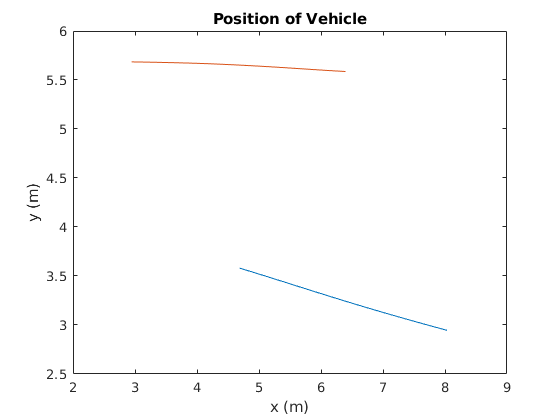

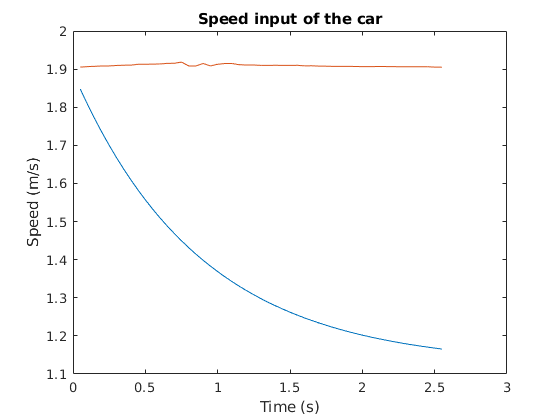

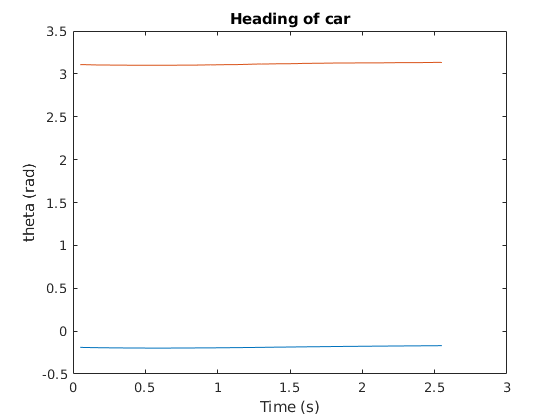

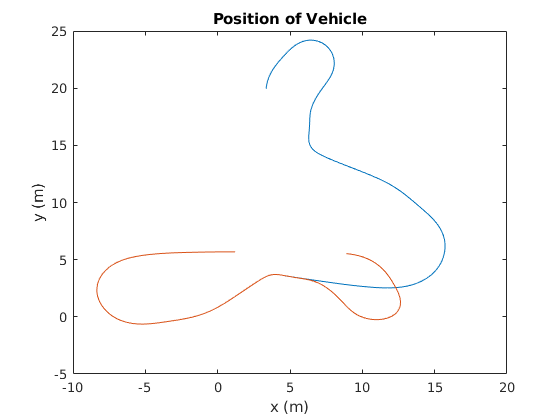

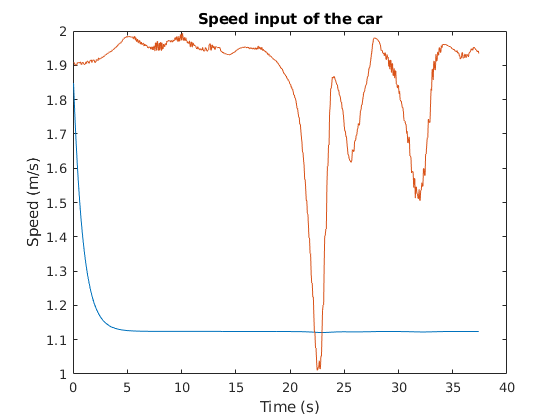



for i=1:length(res)
   plot_res(iddata(res{i}),getexp(data_est,i));
end

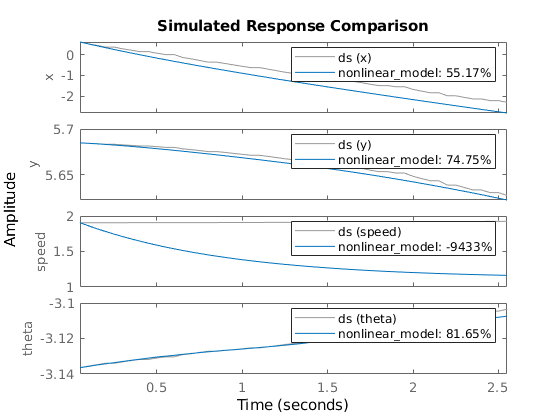

ds = exp7;
initial_states = reshape(ds.y(1,:),[],1);
nonlinear_model = idnlgrey('bicycle_model',order,parameters,initial_states,Ts);
compare(ds,nonlinear_model)